# MK10 Tire Review Script

%=============================================
% MK10 Tire Review Script
% Authors: Rohan Shinde || Jenna Lacuata
% Functions
    % Determine Testing Cases (3)
    % Calculate Tire Forces and Moments using MFeval and .tir files
    % Plot Lateral and Longitudinal Graphs with Additional Formatting
    % Calculate peaks, slopes, behaviour of plots

% For Questions -> Rohan Shinde
%=============================================

## Array & Parameter Extraction

% INSTRUCTIONS:
% -> Try not to change P1 (we chose 12PSI as a test pressure)
% -> Add additional params by extracting correct column from output (check Notion for column info)
% -> Make all calculations here (be sure to change index for each tire)

%tire 1
[FL_Output, FR_Output, RL_Output, RR_Output] = VD11_MFeval_TIR_File_Parser(".\tirFiles\magicformula_R20.tir");

[ FL_ForceZ, FR_ForceZ, RR_ForceZ, RL_ForceZ, kappa, alpha, gamma, phit, Vx, P ] = VD_11_Constants();

TireRawData = {FL_Output, FR_Output, RL_Output, RR_Output}

TireRawData = 1×4 cell array
    {200×30 double}    {200×30 double}    {200×30 double}    {200×30 double}



% creates a struct array of length 4 consisting of: 
% {FL Fields, FR Fields, RL Fields, RR Fields}
clear Tire
for i = 1:4
    Tire(i) = VD11_Process_Tire( TireRawData{i} );
end

## Plotting and Graphical Analysis

% INSTRUCTIONS:
% -> Based on either lat or long analysis, comment and uncomment plotting blocks
% -> For lateral analysis plots - USE LATERAL labelled blocks
% -> For longitudinal plots - USE LONGITUDINAL labelled blocks

% LATERAL: Lateral Force Vs Slip Angle
figure; hold on; grid on

%loops through all 4 tires: for each tire, plot a line on graph
colors = {'r','g','b','y'}

colors = 1×4 cell array
    {'r'}    {'g'}    {'b'}    {'y'}


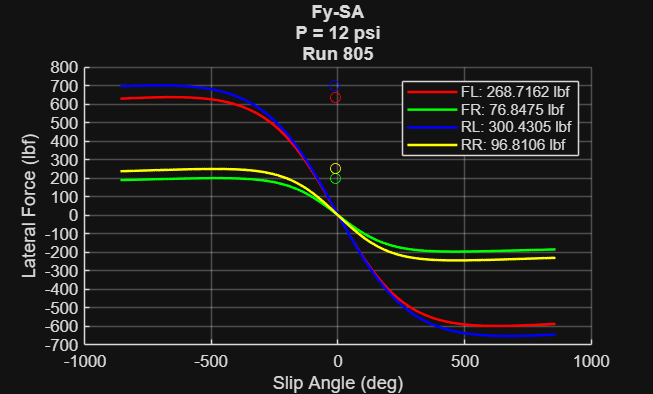


for i = 1:4
    plot(Tire(i).SA, Tire(i).Fy, colors{i}, 'LineWidth', 1.5)
    
    %find max SA and Fy
    [max_Fy, index] = max(Tire(i).Fy);
    max_SA = SA(index);

    %
    plot(max_SA, max_Fy, ['', 'o', colors{i}])
end

ylim([-700,800]);
yticks(-700:(100):800);
title({'Fy-SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']; ['Run 805']})
xlabel('Slip Angle (deg)')
ylabel('Lateral Force (lbf)')
legend({ ...
    ['FL: ' num2str(FL_ForceZ_0) ' lbf']; '';...
    ['FR: ' num2str(FR_ForceZ_0) ' lbf']; '';...
    ['RL: ' num2str(RR_ForceZ_0) ' lbf']; '';...
    ['RR: ' num2str(RL_ForceZ_0) ' lbf']})